[1] M. Li, H. Yan, L. Wang: Nonlinear model reduction for a cantilevered pipe conveying fluid: A system with asymmetric damping and stiffness matrices. MSSP. 2023. [https://doi.org/10.1016/j.ymssp.2022.109993](https://doi.org/10.1016/j.ymssp.2022.109993)

%canti
%clearvars
% close all

## Example setup

The $N$-degree of freedom dynamical system is of the form


$$\mathbf{M\ddot{q}} + \mathbf{C\dot{q}} + \mathbf{Kq} + \mathbf{f}(\mathbf{q},\mathbf{\dot{q}}) 
= \mathbf{0}$$


where $\mathbf{f}=\mathcal{O}(|\mathbf{q}|^2,|\mathbf{\dot{q}}|^2,|\mathbf{q}||\mathbf{\dot{q}}|)$ represents the nonlinearities and $\mathbf{M}$, $\mathbf{C}$, and $\mathbf{K}$ are the $n\times n$ mass, stiffness, and damping matrices, respectively.

We rewrite the system in first-order form as


$$\mathbf{\dot{x}} = \mathbf{A}\mathbf{x} + \mathbf{G}(\mathbf{x}) = \mathbf{F}(\mathbf{x})$$


with

$\mathbf{x}=\left[\begin{array}{c}\mathbf{q}\\\dot{\mathbf{q}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}\mathbf{0}  & \mathbf{I}\\-\mathbf{M}^{-1}\mathbf{K} & -\mathbf{M}^{-1}\mathbf{C} \end{array}\right],\quad\mathbf{G}(\mathbf{x})=\left[\begin{array}{c}  \mathbf{0} \\ -\mathbf{M}^{-1}\mathbf{f}(\mathbf{x})\end{array}\right]$.

% clear all;
import casadi.*

nmodes = 4;
fcload = 0;
flowspeed =27

flowspeed = 27

miu = 0;
Gamma=0;
alpha=1e-5;
beta=0.2;

[M, C, K, fnl, fext] = build_model1(nmodes,flowspeed,beta,miu,Gamma,alpha,'clamped-free','nonlinear_damp');

Getting linear and nonlinearity coefficients
Calculating coefficients
L2 norm of phi1 is 1
L2 norm of phi2 is 1
L2 norm of phi3 is 1
L2 norm of phi4 is 1
Saving coefficients


n = size(M,1);    % mechanical dofs (axial def, transverse def, angle)

Create dynamical system 

DS = DynamicalSystem();
set(DS,'M',M,'C',C,'K',K,'fnl',fnl);
set(DS.Options,'Emax',10,'Nmax',10,'notation','multiindex')
set(DS.Options,'RayleighDamping',false)
[V,D,W] = DS.linear_spectral_analysis();


 The first 8 nonzero eigenvalues are given as 
   1.0e+02 *

   1.6639 + 0.7599i
   1.6639 - 0.7599i
   0.2891 + 0.2461i
   0.2891 - 0.2461i
  -0.3881 + 0.0000i
  -1.2718 + 0.0000i
  -2.0900 + 0.5376i
  -2.0900 - 0.5376i



sigma_out = -1
sigma_in = -1


Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 2.77E-02 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 3.02E-02 MB
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 3.44E-02 MB
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 3.95E-02 MB
Manifold computation time at order 6 = 00:00:00
Estimated memory usage at order  6 = 4.69E-02 MB
Manifold computation time at order 7 = 00:00:00
Estimated memory usage at order  7 = 5.55E-02 MB
Manifold computation time at order 8 = 00:00:00
Estimated memory usage at order  8 = 6.72E-02 MB
Manifold computation time at order 9 = 00:00:00
Estimated memory usage at order  9 = 8.03E-02 MB


$$y = \left(\begin{array}{c} 166.4\,\rho_{1}\\ 75.99 \end{array}\right)$$


phiend = zeros(n,1);
lamda  = zeros(n,1);
lamda(1)=1.8751040687119611664453082410782141625701117335311;
lamda(2)=4.6940911329741745764363917780198120493898967375458;
lamda(3)=7.8547574382376125648610085827645704578485419292300;
lamda(4)=10.995540734875466990667349107854702939612972774652;
lamda(5)=14.137168391046470580917046812551772068603076792975;
lamda(6)=17.278759532088236333543928414375822085934519635550;
lamda(7)=20.420352251041250994415811947947837046137288894544;
lamda(8)=23.561944901806443501520253240198075517031265990051;
for k=1:n
    x    = 1;
    phin = cos(lamda(k)*x)-cosh(lamda(k)*x)-(cos(lamda(k))+cosh(lamda(k)))/(sin(lamda(k))+sinh(lamda(k)))*...
        (sin(lamda(k)*x)-sinh(lamda(k)*x));%clamped-free
    phiend(k) = phin;
end
% disp at the free end
obsfun = @(x,mapx,nmodes) mapx*x(1:nmodes,:);
obs = @(x) obsfun(x,phiend',n);

### create training set

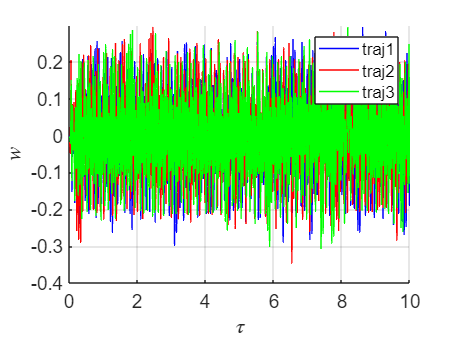

tf     = 10; 
nsteps = 50000;
stepps=nsteps/tf;
z0     = 0.0*V(:,1); % initial condition (here we select it based on the modal shapes)
z0(1)  = 0.001;
outdof = 1:2*n;
set(DS,'u',[]);
traj = transient_traj_on_auto_ssm(DS, resonant_modes, W0, R0, tf, nsteps, outdof, z0);
[tInt,zInt] = time_integration_transient(DS,2*pi/tf,...
    'nSteps', nsteps, 'nCycles', 1, ...
    'integrationMethod','ode45','outdof',outdof,'init',z0);

z02=z0;
z02(1)  = 0.01;
outdof = 1:2*n;
[tInt2,zInt2] = time_integration_transient(DS,2*pi/tf,...
    'nSteps', nsteps, 'nCycles', 1, ...
    'integrationMethod','ode45','outdof',outdof,'init',z02);

z03=z0;
z03(1)  = 0.002;
outdof = 1:2*n;
[tInt3,zInt3] = time_integration_transient(DS,2*pi/tf,...
    'nSteps', nsteps, 'nCycles', 1, ...
    'integrationMethod','ode45','outdof',outdof,'init',z03);

ep=1e-10;
z04=z0;
z04(1)  =z0(1)+ep;
outdof = 1:2*n;
[tInt4,zInt4] = time_integration_transient(DS,2*pi/tf,...
    'nSteps', nsteps, 'nCycles', 1, ...
    'integrationMethod','ode45','outdof',outdof,'init',z04);

z05 = [-0.0428094872008768;	0.0197913138572779;	0.0285853168586361;	-0.00665049949500384;	-14.5733724149122	;-5.86628543680450	;7.82640716177011;	5.11544706881291];
outdof = 1:2*n;
[tInt5,zInt5] = time_integration_transient(DS,2*pi/tf,...
    'nSteps', nsteps, 'nCycles', 1, ...
    'integrationMethod','ode45','outdof',outdof,'init',z05);

z06=z0;
z06(1)  = 0.03;
z06(2)  = 0.01;
outdof = 1:2*n;
[tInt6,zInt6] = time_integration_transient(DS,2*pi/tf,...
    'nSteps', nsteps, 'nCycles', 1, ...
    'integrationMethod','ode45','outdof',outdof,'init',z06);

z07=z0;
z07=[-0.0528094872008768;	0.0197913138572779;	0.0185853168586361;	-0.00665049949500384;	-14.5733724149122	;-2.86628543680450	;7.82640716177011;	5.11544706881291];
outdof = 1:2*n;
[tInt7,zInt7] = time_integration_transient(DS,2*pi/tf,...
    'nSteps', nsteps, 'nCycles', 1, ...
    'integrationMethod','ode45','outdof',outdof,'init',z07);

z08=z0;
z08(1)  = 0.01;
z08(2)  = 0.01;
outdof = 1:2*n;
[tInt8,zInt8] = time_integration_transient(DS,2*pi/tf,...
    'nSteps', nsteps, 'nCycles', 1, ...
    'integrationMethod','ode45','outdof',outdof,'init',z08);


z09=[0.0418637084535072	;-0.00351253709096715	;0.0120981881925155	;0.00721290708966405;	0.0140245654620291	;0.0376932281345892	;-0.456493667863058	;-0.948561787357355];
outdof = 1:2*n;
[tInt9,zInt9] = time_integration_transient(DS,2*pi/tf,...
    'nSteps', nsteps, 'nCycles', 1, ...
    'integrationMethod','ode45','outdof',outdof,'init',z09);

z10=[-0.117331041553083; -0.0897442124166163; -0.0170896655650246; 0.0065071908500552; -5.23310043042533; -14.7030603258779; 10.8720041865659; -7.56972825830502];
outdof = 1:2*n;
[tInt10,zInt10] = time_integration_transient(DS,2*pi/tf,...
    'nSteps', nsteps, 'nCycles', 1, ...
    'integrationMethod','ode45','outdof',outdof,'init',z10);

figure;hold on
%plot(traj.time,traj.phy(:,1:n)*phiend,'r-','LineWidth',1); hold on
plot(tInt,zInt(:,1:n)*phiend,'b-','LineWidth',1);
plot(tInt,zInt2(:,1:n)*phiend,'r-','LineWidth',1);
plot(tInt,zInt3(:,1:n)*phiend,'g-','LineWidth',1);
xlabel('$\tau$','Interpreter',"latex",'FontSize',14);
ylabel('$w$','Interpreter',"latex",'FontSize',14);
set(gca,'FontSize',14); grid on
legend('traj1','traj2','traj3')
xlim([0,min(traj.time(end),tInt(end))]);


speedT=zInt(:,n+1:end)*phiend

speedT =          0
   -0.0001
   -0.0003
   -0.0004
   -0.0004
   -0.0005
   -0.0006
   -0.0006
   -0.0006
   -0.0006


speed=speedT'

speed =          0   -0.0001   -0.0003   -0.0004   -0.0004   -0.0005   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0005   -0.0005   -0.0004   -0.0004   -0.0003   -0.0002   -0.0001    0.0000    0.0001    0.0002    0.0004    0.0005    0.0007    0.0008    0.0010    0.0011    0.0013    0.0015    0.0016    0.0018    0.0020    0.0022    0.0024    0.0026    0.0027    0.0029    0.0031    0.0033    0.0035    0.0037    0.0039    0.0041    0.0043    0.0045    0.0047    0.0049    0.0050    0.0052


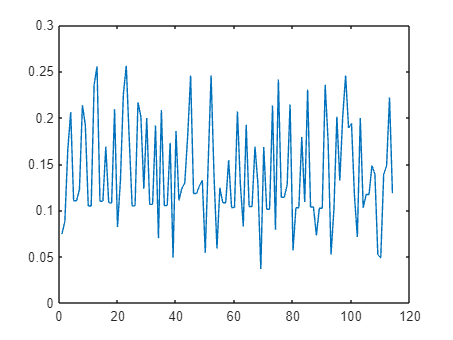

disp1=zInt(:,1:n)*phiend;
speed0=[];

for i=1:size(speed,2)
    if (abs(speed(i))<0.1) && (disp1(i)>0)
        speed0=[speed0,i];
    end
end

figure()
plot(disp1(speed0))


auData = construct_autoData(DS, resonant_modes, R0);
tspan  = linspace(0,tf,nsteps);
Bext     = phiend;
epsilon  = 1;
set(DS,'D',Bext,'epsilon',epsilon);
set(DS.Options, 'outDOF', outdof);
om = 2*pi/tf;


### SSM Learn

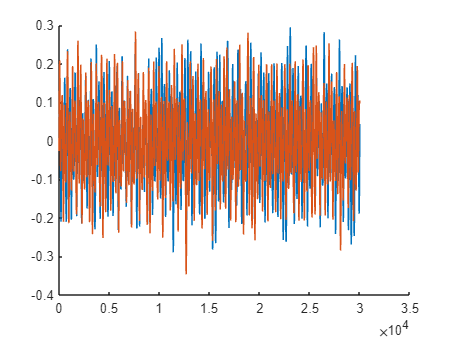

close all

useddim=[1];
SSMstart=20000;

NMTEmin=10000000000000;

xalldimwo=zInt(:,1:n)*phiend;
xalldimwo2=zInt2(:,1:n)*phiend;
xalldimwo3=zInt3(:,1:n)*phiend;
xalldimwo4=zInt4(:,1:n)*phiend;
xalldimwo5=zInt5(:,1:n)*phiend;
xalldimwo6=zInt6(:,1:n)*phiend;
xalldimwo7=zInt7(:,1:n)*phiend;
xalldimwo8=zInt8(:,1:n)*phiend;
xalldimwo9=zInt9(:,1:n)*phiend;
xalldimwo10=zInt10(:,1:n)*phiend;

SSMDim=3;
xfullwoT=xalldimwo(SSMstart:end,useddim)';
xfullwoT2=xalldimwo2(SSMstart:end,useddim)';
xfullwoT3=xalldimwo3(SSMstart:end,useddim)';
xfullwoT4=xalldimwo4(SSMstart:end,useddim)';
xfullwoT5=xalldimwo5(SSMstart:end,useddim)';
xfullwoT6=xalldimwo6(SSMstart:end,useddim)';
xfullwoT7=xalldimwo7(SSMstart:end,useddim)';
xfullwoT8=xalldimwo8(SSMstart:end,useddim)';
xfullwoT9=xalldimwo9(SSMstart:end,useddim)';
xfullwoT10=xalldimwo10(SSMstart:end,useddim)';

figure();hold on
plot(xfullwoT(1,:))
plot(xfullwoT2(1,:))

%xfullwoT=xfullwo(:,1)';
lengthT=size(xfullwoT,2);
tspan=linspace(0,lengthT/stepps,lengthT)

tspan =          0    0.0002    0.0004    0.0006    0.0008    0.0010    0.0012    0.0014    0.0016    0.0018    0.0020    0.0022    0.0024    0.0026    0.0028    0.0030    0.0032    0.0034    0.0036    0.0038    0.0040    0.0042    0.0044    0.0046    0.0048    0.0050    0.0052    0.0054    0.0056    0.0058    0.0060    0.0062    0.0064    0.0066    0.0068    0.0070    0.0072    0.0074    0.0076    0.0078    0.0080    0.0082    0.0084    0.0086    0.0088    0.0090    0.0092    0.0094    0.0096    0.0098



SSMtrainnum=1

SSMtrainnum = 1

ydatac=cell(1,2);

indtrain=[1 2 3 4 5 6 7 8 9 ]

indtrain =      1     2     3     4     5     6     7     8     9



ydatac{1,1}=tspan;
ydatac{2}=xfullwoT(:,1:end-1);
ydatac{1,2}=xfullwoT;
ydatac{2,1}=tspan;
ydatac{2,2}=xfullwoT2;
ydatac{3,1}=tspan;
ydatac{3,2}=xfullwoT3;
ydatac{4,1}=tspan;
ydatac{4,2}=xfullwoT4;
ydatac{5,1}=tspan;
ydatac{5,2}=xfullwoT5;
ydatac{6,1}=tspan;
ydatac{6,2}=xfullwoT6;
ydatac{7,1}=tspan;
ydatac{7,2}=xfullwoT7;
ydatac{8,1}=tspan;
ydatac{8,2}=xfullwoT8;
ydatac{9,1}=tspan;
ydatac{9,2}=xfullwoT9;
ydatac{10,1}=tspan;
ydatac{10,2}=xfullwoT10;

overEmbed = 0;
ydataembed = coordinatesEmbedding(ydatac, SSMDim, 'OverEmbedding', overEmbed);

The 7 embedding coordinates consist of the measured state and its 6 time-delayed measurements.



SSMOrder = 6;
[IMInfo, SSMChart, SSMFunction] = IMGeometry(ydataembed(indtrain,:), SSMDim, SSMOrder);%ydata可以是nxN的矩阵（zauto）

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    1.485660e-12    1.953e-03    3.894e-19

收敛于不可行点。

fmincon 已停止，因为当前步长小于
步长容差的值，但在约束容差值范围内不满足约束。

<停止条件详细信息>

请考虑启用内点法可行性模式。



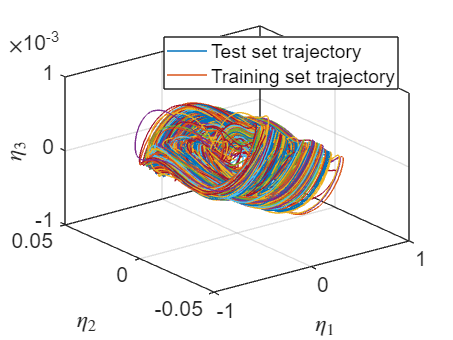



etaData = projectTrajectories(IMInfo, ydataembed);%Use the chart of a manifold to transform trajectories in the observable space to reduced coordinates on the manifold.

plotReducedCoordinates(etaData);view(3);%fig3 画出测试集和训练集的轨迹?
legend({'Test set trajectory', 'Training set trajectory'})



plotSSMWithTrajectories(IMInfo, 1, ydataembed)%figure4 测试和流形

SSM plotting only available for 1D and 2D manifolds


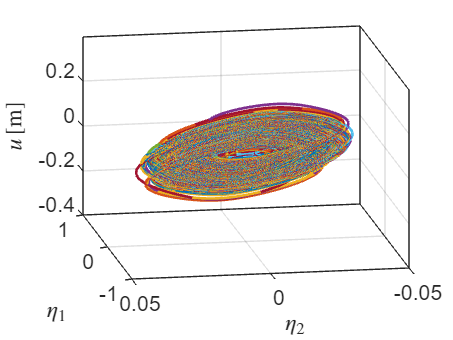

view(-100,20); zlabel('$u \, [$m$]$','Interpreter','latex')


yyData = transformTrajectories(IMInfo.parametrization.map, etaData);
normedTrajDist = computeTrajectoryErrors(ydataembed, yyData);
Error = mean(normedTrajDist)

Error = 3.0663e-06

fig =   Figure (11) - 属性:

      Number: 11
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 818 560 420]
       Units: 'pixels'

  显示 所有属性


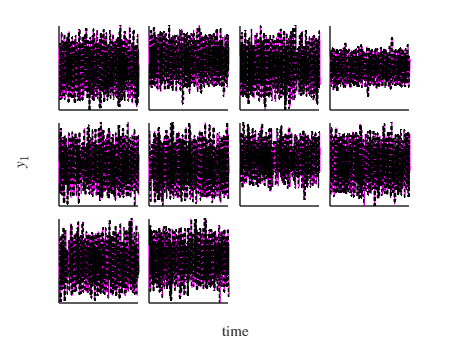

% plot static reconstruction to show manifold fitting quality
plotTrajectories(ydataembed, yyData, 'm', 1, {'Test set', 'Static prediction'})


ROMOrder = 12

ROMOrder = 12

RDInfo = IMDynamicsFlow(etaData,  'R_PolyOrd', ROMOrder, 'style', 'normalform');

Estimation of the reduced dynamics...  Done. 
Estimation of the reduced dynamics in normal form...
Normal form not available. Returning modal style.


[yRec, etaRec, zRec] = advect(IMInfo, RDInfo, ydataembed);%通过流形 IMInfo 上 RDInfo 中的来advect yData 中的初始条件。？

plotTrajectories(ydataembed(1,:), yRec, 'm', 'DisplayName', {'Test set', 'Prediction'})

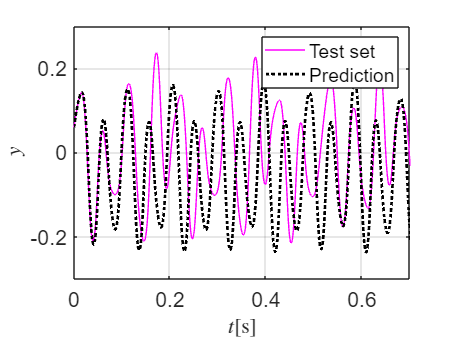

xlim([0 0.7]);ylabel('$y$','Interpreter','latex','FontSize',16);
xlabel('$t\rm{[s]}$','Interpreter','latex','FontSize',16);


%  normedTrajDist = computeTrajectoryErrors(yRec, ydataembedtc);
NMTE = mean(normedTrajDist) % conjugacy error

NMTE = 3.0663e-06

iotm = 50001

jotm = 3

kotm = 4

### LSTM train data

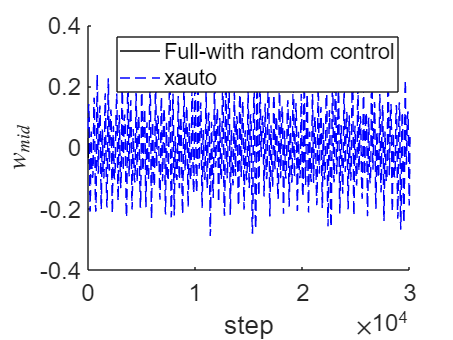

ustart=1;
SSMstart=ustart+SSMstart;
multrainnum=2;
z0ssmstart=zInt(SSMstart+1,:);
omega0=25;

xalldimtotalsp=[];
xautototalsp=[];
LSTMdata4=[];

for expo=1:320
    urandtotalsp=[];
    for A=1:1
        for k=1:multrainnum
            omegatrain=(omega0+(k-1)*20);
            utlength=ceil(2*pi/omegatrain*stepps);
            while utlength>10
                utlength=10;
            end
            urandallsp=zeros(1,utlength);

            for i=1:1:utlength
                for j=1:1
                    urandallsp(j,i)=((-1)^expo)*(0.15*expo)*1e1*sin(omegatrain/stepps*i+expo);
                end
            end
            urandtotalsp=[urandtotalsp,urandallsp];
        end
    end


    totaldatalength=size(urandtotalsp,2);
    if totaldatalength>nsteps-SSMstart
        totaldatalength=nsteps-SSMstart;
        urandtotalsp=urandtotalsp(:,1:totaldatalength);
    end
    nstepsp=totaldatalength;
    tfsp=(totaldatalength)/stepps;
    urandtime=linspace(0,tfsp,nstepsp);
    omsp = 2*pi/tfsp;
    ufun = @(t) transpose(interp1(urandtime,urandtotalsp',t));
    set(DS,'u',ufun)
    [tfullwRcsp, xfullwRcsp,~,xalldimsp] = time_integration_transient(DS,omsp,'nCycles',...
        1, 'nSteps', nstepsp,...
        'integrationMethod','ode15s','outdof',outdof,'init',z0ssmstart);


    xphiend=xalldimsp(:,1:n)*phiend;
    xphiendlength=size(xphiend,1);
    LSTMdata2=[xphiend(1:end-1),urandtotalsp(1,1:xphiendlength-1)',xphiend(2:end)];

    Xep=xphiend-zInt(SSMstart+expo-1:SSMstart+expo+xphiendlength-2,1:n)*phiend;
    LSTMdata3=[Xep(1:end-1),urandtotalsp(1,1:xphiendlength-1)',Xep(2:end)];
    LSTMdata4=[LSTMdata4;LSTMdata3];

    z0ssmstart=zInt(SSMstart+expo,:);
end

save("LSTMdata4.mat",'LSTMdata4')

figure;hold on
plot(xalldimsp(:,1:4)*phiend,'k-','DisplayName', 'Full-with random control');
plot(xalldimwo(1:9000,4)','r--','DisplayName', 'Full-without control')
plot(xalldimwo(SSMstart:end,1)','b--','DisplayName', 'xauto');
legend("show")
xlabel("step")
ylabel("$w_{mid}$",'Interpreter','latex')
set(gca,'FontSize',18)

### MPC

import casadi.*
load LSTM4.mat

mpcsec=0.4;
mpciter=mpcsec*stepps

mpciter = 2000


predictsec=0.03;
T     = predictsec;  % control horizon
Np    = predictsec*stepps;  % number of control intervals
X0=0;
x0_last=0;

ufull=[];
udim=1;
uthres=1500;
DelR=0;

z0mpc=zInt(SSMstart+5,:);
z0mpcphiend=z0mpc(:,1:4)*phiend;
z0mpc7dim=ydataembed{1,2}(:,1);
zall=[z0mpcphiend];

Q  = 1e3*1;
R  = 0.00001;

SSMfaultnum=0;

preally=[];
yu0=predict(net,[0;0]);
yu0=double(yu0);

h=300;
u_guess=[-2*h,-h,h,2*h];
sim=zeros(1,4);

for nodes=1:4
    sim(nodes)=predict(net,[0;u_guess(nodes)]);
end

dxdu=(sim(1)-8*sim(2)+8*sim(3)-sim(4))/(12*h);

set(DS,'u',[])
[tIntwo,zIntwo] = time_integration_transient(DS,2*pi/tf,...
    'nSteps', nsteps, 'nCycles', 1, ...
    'integrationMethod','ode45','outdof',outdof,'init',z0mpc);
zallwo=zIntwo(:,1:n)*phiend;

for iter=1:mpciter

    advectmpc=cell(1,2);
    advectmpc{1,1}=tspan(:,1:Np);
    advectmpc{1,2}=repmat(z0mpc7dim,1,Np);
    [yRecmpc, etaRec, zRec] = advect(IMInfo, RDInfo, advectmpc);
    realSSMy=real(yRecmpc{1,2}(7,:));
    Q=Q+20;
    if Q>40*1e3
        Q=40*1e3;
    end

    SSMnexty=(realSSMy(:,1));

    u=-1*(2*Q*dxdu*(SSMnexty+yu0))/(2*R+Q*dxdu^2);

    if u<- uthres
        u=-uthres;
    end
    if u>uthres
        u=uthres;
    end

    lstmPRE=predict(net,[0;u]);
    prey=SSMnexty+lstmPRE;

    umpc_length=10;
    utrep=repmat(u,1,umpc_length);
    umpc_sec=umpc_length/stepps;
    tspan_umpc=linspace(0,umpc_sec,umpc_length);
    ommpc = 2*pi/umpc_sec;
    ufun = @(t) transpose(interp1(tspan_umpc,utrep,t));
    set(DS,'u',ufun)
    [t_umpc, xfullmpc,~,xalldimmpc] = time_integration_transient(DS,ommpc,'nCycles',...
        1, 'nSteps',umpc_length,...
        'integrationMethod','ode15s','outdof',outdof,'init',z0mpc);

    y0real2=xalldimmpc(2,1:n)*phiend;

    ufull=[ufull,u];
    zall=[zall,z0mpcphiend];

    z0mpc=xalldimmpc(2,:);

    z0mpcphiend=z0mpc(:,1:n)*phiend;
    z0mpc7dim=[z0mpc7dim(2:end,:);z0mpcphiend];

    preally=[preally,prey];
    
end



figlength=size(zall,2)-1

figlength = 2000

figx=linspace(0,figlength/stepps,figlength)

figx =          0    0.0002    0.0004    0.0006    0.0008    0.0010    0.0012    0.0014    0.0016    0.0018    0.0020    0.0022    0.0024    0.0026    0.0028    0.0030    0.0032    0.0034    0.0036    0.0038    0.0040    0.0042    0.0044    0.0046    0.0048    0.0050    0.0052    0.0054    0.0056    0.0058    0.0060    0.0062    0.0064    0.0066    0.0068    0.0070    0.0072    0.0074    0.0076    0.0078    0.0080    0.0082    0.0084    0.0086    0.0088    0.0090    0.0092    0.0094    0.0096    0.0098


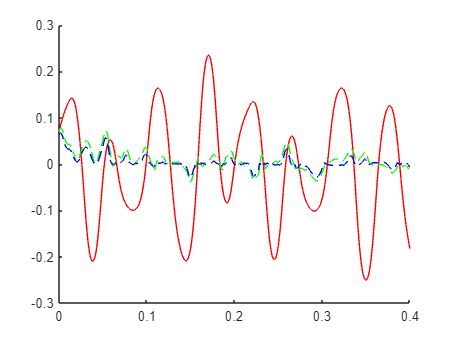

figure()
hold on
plot(figx,  zallwo(1:figlength,1),'r-','DisplayName', 'Full-without control');
plot(figx,  zall(1,1:figlength),'g--','DisplayName', 'Full-with control');
plot(figx, preally(1,1:figlength),'b--','DisplayName', 'pre Full-with control')

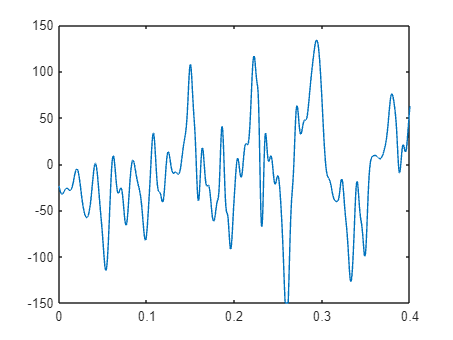


figure()
plot(figx(1:end),0.1*ufull)